% Try dPCA and method in Matt's paper to look at null and potent subspaces
%
%
%

clear
clf

data_one_trial = prepData();

data_multiple_trial = prepData();

725/725


position = data_one_trial.Kinematics.ActualPos;

Unable to resolve the name 'data_one_trial.Kinematics.ActualPos'.

velocity = data_one_trial.Kinematics.Actual;

neural_lfp_data = data_one_trial.LFP.raw;

Unable to resolve the name 'data_one_trial.LFP.raw'.

figure
for channel_idx = 1:256
    single_channel_data = neural_lfp_data(:, channel_idx);
    subplot(16,16,channel_idx);
    plot(1:2800, single_channel_data)
    title("Channel " + channel_idx)
    xlabel("Time")
    ylabel("Signal")
end

x_data = position(:, 2);
y_data = position(:, 3);
figure
subplot(2,1,1)
plot(x_data, x_data);
title("Cursor movement")
xlabel("x pos")
ylabel("y pos")
subplot(2,1,2)
plot(x_data, y_data);
title("Cursor movement")
xlabel("x pos")
ylabel("y pos")

spike_counts = data_one_trial.SpikeCount

spike_counts_binary = spike_counts
spike_counts_binary(spike_counts_binary >= 1) = 1
spike_counts_binary = spike_counts_binary.'

figure
imagesc(~spike_counts_binary)
cmap = gray(256);
% Set one gray level, 8, to red.
% Remember, row #1 is 0 gray levels.
% so row #9 is 8 gray levels.
cmap(9,:) = [1,0,0];
colormap(cmap); % Apply the custom colormap
set(gca,'xtick',[])
set(gca,'xticklabel',[])
set(gca,'ytick',[])
title("Raster Plot for Trial 1")
xlabel("Time (ms)")
ylabel("Spikes")

%% This section creates toy data.
%
% It should be replaced by actual experimental data. The data should be
% joined in three arrays of the following sizes (for the Romo-like task):
%
% trialNum: N x S x D
% firingRates: N x S x D x T x maxTrialNum
% firingRatesAverage: N x S x D x T
%
% N is the number of neurons
% S is the number of stimuli conditions (F1 frequencies in Romo's task)
% D is the number of decisions (D=2)
% T is the number of time-points (note that all the trials should have the
% same length in time!)
%
% trialNum -- number of trials for each neuron in each S,D condition (is
% usually different for different conditions and different sessions)
%
% firingRates -- all single-trial data together, massive array. Here
% maxTrialNum is the maximum value in trialNum. E.g. if the number of
% trials per condition varied between 1 and 20, then maxTrialNum = 20. For
% the neurons and conditions with less trials, fill remaining entries in
% firingRates with zeros or nans.
%
% firingRatesAverage -- average of firingRates over trials (5th dimension).
% If the firingRates is filled up with nans, then it's simply
%    firingRatesAverage = nanmean(firingRates,5)
% If it's filled up with zeros (as is convenient if it's stored on hard 
% drive as a sparse matrix), then 
% firingRatesAverage = bsxfun(@times, mean(firingRates,5), size(firingRates,5)./trialNum)

active_channel_mask = data_multiple_trial.ActiveChannelMask

active_channel_mask = 1280×1 logical array
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0



spike_counts = data_multiple_trial.SpikeCount(:, active_channel_mask)

spike_counts =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    


trial_averaged_rates = nanmean(spike_counts, 1)

trial_averaged_rates =     0.0064    0.0066    0.0074    0.0065    0.0056    0.0063    0.0063    0.0060    0.0428    0.0045    0.0062    0.0074    0.0063    0.0065    0.0055    0.0065    0.0079    0.0067    0.0047    0.0059    0.0059    0.0054    0.0072    0.0071    0.0059    0.0057    0.0070    0.0048    0.0097    0.0057    0.0064    0.0225    0.0215    0.0222    0.0199    0.0285    0.0227    0.0245    0.0217    0.0169    0.0183    0.0228    0.0164    0.0885    0.0188    0.0204    0.0303    0.0111    0.0198    0.0206



%trial_num = [trial_averaged_rates data_multiple_trial.TaskStateMasks.targ_idx.']

trial_and_target = [data_multiple_trial.trial_num; data_multiple_trial.TaskStateMasks.target_name]

trial_and_target =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



trial_and_target = trial_and_target(:, trial_and_target(2,:) > 0)

trial_and_target =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



trial_num = zeros(251, max(data_multiple_trial.TaskStateMasks.target_name), 1);

for neuron_idx=1:251
    for decision_idx=1:max(trial_and_target, [], 'all')
        filtered_by_trial_idx = trial_and_target(:, find(trial_and_target(1, :) == decision_idx));
        unique_target_ids_per_trial = unique(filtered_by_trial_idx(2,:));
        for i=1:length(unique_target_ids_per_trial)
            unique_target_ids_per_trial(i) + 1;
            trial_num(neuron_idx, unique_target_ids_per_trial(i), 1) = trial_num(neuron_idx, unique_target_ids_per_trial(i), 1) + 1;
        end
    end
end

trial_num

trial_num =     33
    33
    33
    33
    33
    33
    33
    33
    33
    33




%%gets max trial number
[uPhase,ia,ic] = unique(data_multiple_trial.trial_num);
tally = accumarray(ic, 1);
max_trial_num = max(tally)

max_trial_num = 49452

max(trial_num(:))

ans = 33




arr = [];

%max 1278
firing_rates = zeros(251, 10, 1, 110, max(trial_num(:))); %10 hard coded?
last_idx = 1;
for trial_idx=0:10
    spike_counts_max_time_points = zeros(110, 251);

    trial_target_idx = find(trial_and_target(2,:)==trial_idx);

    for i=1:unique(trial_and_target(1, trial_target_idx))
         trial_target_idx = find(trial_and_target(2,:)==trial_idx & trial_and_target(1,:)==i);

         arr = [arr length(trial_target_idx)];

        spike_counts_max_time_points(1:length(trial_target_idx), :) = spike_counts(trial_target_idx, :);
        firing_rates(:, trial_idx, 1, :, i) = spike_counts_max_time_points.';
    end
end

Unable to perform assignment because the size of the left side is 251-by-1-by-1-by-110 and the size of the right side is 251-by-7602.




%firingRatesAverage = nanmean(firing_rates, 5);



firing_rates_average = bsxfun(@times, mean(firing_rates,5), size(firing_rates,5)./trial_num)


%%how to handle variable length trials
%%get max trial time points and add padding for any with lesser
% 
% firing_rates = zeros(231, 10, 719, max(trial_num(:))); %10 hard coded?
% last_idx = 1;
% for trial_idx=1:52
%     spike_counts_max_time_points = zeros(719, 234);
% 
%     if trial_idx ~= 1
%         filter_idx = tally(trial_idx) + last_idx
%         spike_counts_max_time_points(1:length(last_idx+1:filter_idx), :) = spike_counts(last_idx+1:filter_idx, :)
%     else
%         filter_idx = tally(trial_idx)
%         spike_counts_max_time_points(1:length(last_idx:filter_idx), :) = spike_counts(last_idx:filter_idx, :)
%     end
% 
%     last_idx = filter_idx
% end

%%go through and append zeros for trials shorted than 719
%%go through and append zeros for decisions with less than 12



firingRatesAverage = firing_rates_average;





%% Step 1: PCA of the dataset
combinedParams = {{1, [1 3]}, {2, [2 3]}, {3}, {[1 2], [1 2 3]}};
time = 1:110

time =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


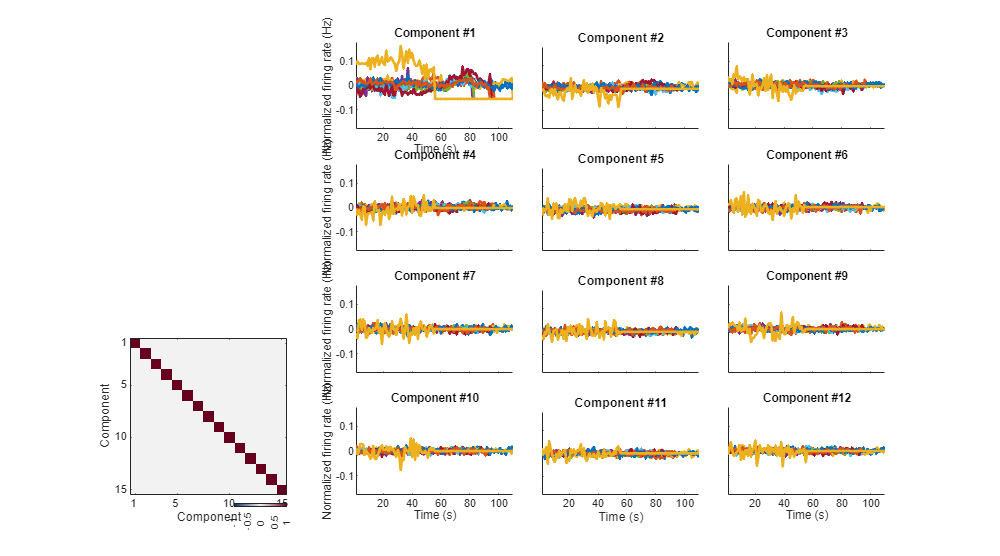



X = firingRatesAverage(:,:);
X = bsxfun(@minus, X, mean(X,2));

[W,~,~] = svd(X, 'econ');
W = W(:,1:20);

% minimal plotting
dpca_plot(firingRatesAverage, W, W, @dpca_plot_default);


% computing explained variance
explVar = dpca_explainedVariance(firingRatesAverage, W, W, ...
    'combinedParams', combinedParams);

% a bit more informative plotting
% dpca_plot(firingRatesAverage, W, W, @dpca_plot_default, ...
%     'explainedVar', explVar, ...
%     'time', time,                        ...
%     'timeEvents', timeEvents,               ...
%     'marginalizationNames', margNames, ...
%     'marginalizationColours', margColours);

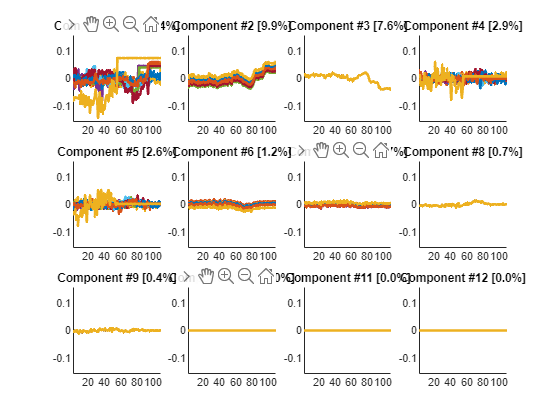

%% Step 2: PCA in each marginalization separately

dpca_perMarginalization(firingRatesAverage, @dpca_plot_default, ...
   'combinedParams', combinedParams);


%% Step 3: dPCA without regularization and ignoring noise covariance

% This is the core function.
% W is the decoder, V is the encoder (ordered by explained variance),
% whichMarg is an array that tells you which component comes from which
% marginalization

tic
[W,V,whichMarg] = dpca(firingRatesAverage, 20, ...
    'combinedParams', combinedParams);

Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10


toc

Elapsed time is 0.097286 seconds.



explVar = dpca_explainedVariance(firingRatesAverage, W, V, ...
    'combinedParams', combinedParams);

dpca_plot(firingRatesAverage, W, V, @dpca_plot_default, ...
    'explainedVar', explVar, ...
    'marginalizationNames', margNames, ...
    'marginalizationColours', margColours, ...
    'whichMarg', whichMarg,                 ...
    'time', time,                        ...
    'timeEvents', timeEvents,               ...
    'timeMarginalization', 3, ...
    'legendSubplot', 16);

Unrecognized function or variable 'margNames'.

%% Step 4: dPCA with regularization

% This function takes some minutes to run. It will save the computations 
% in a .mat file with a given name. Once computed, you can simply load 
% lambdas out of this file:
%   load('tmp_optimalLambdas.mat', 'optimalLambda')

% Please note that this now includes noise covariance matrix Cnoise which
% tends to provide substantial regularization by itself (even with lambda set
% to zero).

optimalLambda = dpca_optimizeLambda(firingRatesAverage, firingRates, trialNum, ...
    'combinedParams', combinedParams, ...
    'simultaneous', ifSimultaneousRecording, ...
    'numRep', 2, ...  % increase this number to ~10 for better accuracy
    'filename', 'tmp_optimalLambdas.mat');

Unrecognized function or variable 'ifSimultaneousRecording'.


Cnoise = dpca_getNoiseCovariance(firingRatesAverage, ...
    firingRates, trialNum, 'simultaneous', ifSimultaneousRecording);

[W,V,whichMarg] = dpca(firingRatesAverage, 20, ...
    'combinedParams', combinedParams, ...
    'lambda', optimalLambda, ...
    'Cnoise', Cnoise);

explVar = dpca_explainedVariance(firingRatesAverage, W, V, ...
    'combinedParams', combinedParams);

dpca_plot(firingRatesAverage, W, V, @dpca_plot_default, ...
    'explainedVar', explVar, ...
    'marginalizationNames', margNames, ...
    'marginalizationColours', margColours, ...
    'whichMarg', whichMarg,                 ...
    'time', time,                        ...
    'timeEvents', timeEvents,               ...
    'timeMarginalization', 3,           ...
    'legendSubplot', 16);

%% Optional: estimating "signal variance"

explVar = dpca_explainedVariance(firingRatesAverage, W, V, ...
    'combinedParams', combinedParams, ...
    'Cnoise', Cnoise, 'numOfTrials', trialNum);

Unrecognized function or variable 'Cnoise'.


% Note how the pie chart changes relative to the previous figure.
% That is because it is displaying percentages of (estimated) signal PSTH
% variances, not total PSTH variances. See paper for more details.

dpca_plot(firingRatesAverage, W, V, @dpca_plot_default, ...
    'explainedVar', explVar, ...
    'marginalizationNames', margNames, ...
    'marginalizationColours', margColours, ...
    'whichMarg', whichMarg,                 ...
    'time', time,                        ...
    'timeEvents', timeEvents,               ...
    'timeMarginalization', 3,           ...
    'legendSubplot', 16);

%% Optional: decoding

decodingClasses = {[(1:S)' (1:S)'], repmat([1:2], [S 1]), [], [(1:S)' (S+(1:S))']};

Unrecognized function or variable 'S'.


accuracy = dpca_classificationAccuracy(firingRatesAverage, firingRates, trialNum, ...
    'lambda', optimalLambda, ...
    'combinedParams', combinedParams, ...
    'decodingClasses', decodingClasses, ...
    'simultaneous', ifSimultaneousRecording, ...
    'numRep', 5, ...        % increase to 100
    'filename', 'tmp_classification_accuracy.mat');

dpca_classificationPlot(accuracy, [], [], [], decodingClasses)

accuracyShuffle = dpca_classificationShuffled(firingRates, trialNum, ...
    'lambda', optimalLambda, ...
    'combinedParams', combinedParams, ...
    'decodingClasses', decodingClasses, ...
    'simultaneous', ifSimultaneousRecording, ...
    'numRep', 5, ...        % increase to 100
    'numShuffles', 20, ...  % increase to 100 (takes a lot of time)
    'filename', 'tmp_classification_accuracy.mat');

dpca_classificationPlot(accuracy, [], accuracyShuffle, [], decodingClasses)

componentsSignif = dpca_signifComponents(accuracy, accuracyShuffle, whichMarg);

dpca_plot(firingRatesAverage, W, V, @dpca_plot_default, ...
    'explainedVar', explVar, ...
    'marginalizationNames', margNames, ...
    'marginalizationColours', margColours, ...
    'whichMarg', whichMarg,                 ...
    'time', time,                        ...
    'timeEvents', timeEvents,               ...
    'timeMarginalization', 3,           ...
    'legendSubplot', 16,                ...
    'componentsSignif', componentsSignif);

%% This section creates toy data.
%
% It should be replaced by actual experimental data. The data should be
% joined in three arrays of the following sizes (for the Romo-like task):
%
% trialNum: N x S x D
% firingRates: N x S x D x T x maxTrialNum
% firingRatesAverage: N x S x D x T
%
% N is the number of neurons
% S is the number of stimuli conditions (F1 frequencies in Romo's task)
% D is the number of decisions (D=2)
% T is the number of time-points (note that all the trials should have the
% same length in time!)
%
% trialNum -- number of trials for each neuron in each S,D condition (is
% usually different for different conditions and different sessions)
%
% firingRates -- all single-trial data together, massive array. Here
% maxTrialNum is the maximum value in trialNum. E.g. if the number of
% trials per condition varied between 1 and 20, then maxTrialNum = 20. For
% the neurons and conditions with less trials, fill remaining entries in
% firingRates with zeros or nans.
%
% firingRatesAverage -- average of firingRates over trials (5th dimension).
% If the firingRates is filled up with nans, then it's simply
%    firingRatesAverage = nanmean(firingRates,5)
% If it's filled up with zeros (as is convenient if it's stored on hard 
% drive as a sparse matrix), then 
%    firingRatesAverage = bsxfun(@times, mean(firingRates,5), size(firingRates,5)./trialNum)

clear all

N = 100;%100;   % number of neurons
T = 20;%20;     % number of time points
S = 7;%7;       % number of stimuli
D = 2;          % number of decisions
E = 20;%20;     % maximal number of trial repetitions

% generating three components
time = (1:T) / 10;
component{1} = bsxfun(@times, ones(1,S,D,T,E), shiftdim(sin(time), -2)) * 20;
component{2} = bsxfun(@times, ones(1,S,D,T,E), (1:S)-ceil(S/2)) .* bsxfun(@times, ones(1,S,D,T,E), shiftdim(time, -2));
component{3} = bsxfun(@times, ones(1,S,D,T,E), shiftdim([-1 1],-1)) .* ...
    bsxfun(@times, ones(1,S,D,T,E), shiftdim([time(1:end/2)*0 time(1:end/2)], -2)) * 6;

% mixing them randomly along non-orthogonal axes
V = randn(N, length(component));
V(:,2) = V(:,2) + V(:,1)/3;
V(:,3) = V(:,3) + V(:,2)/4;
V = bsxfun(@times, V, 1./sqrt(sum(V.^2)));
for c = 1:length(component)
    components(:,c) = component{c}(:,:);
end
firingRates = V*components';
clear component components 

% adding noise and normalizing
firingRates = firingRates + randn(size(firingRates));
firingRates = firingRates - min(firingRates(:)) + 10;
firingRates = reshape(firingRates, [N S D T E]);

% setting random number of repetitions for each neuron and condition
ifSimultaneousRecording = false;  % change this to simulate simultaneous 
                                 % recordings (they imply the same number 
                                 % of trials for each neuron)
if ~ifSimultaneousRecording
    trialNum = randi([5 E], [N S D]);
else
    trialNum = repmat(randi([5 E], [1 S D]), [N 1 1]);
end

for n = 1:N
    for s = 1:S
        for d = 1:D
            firingRates(n,s,d,:,trialNum(n,s,d)+1:E) = nan;
        end
    end
end

% computing PSTHs
firingRatesAverage = nanmean(firingRates, 5);

%% Define parameter grouping

% *** Don't change this if you don't know what you are doing! ***
% firingRates array has [N S D T E] size; herewe ignore the 1st dimension 
% (neurons), i.e. we have the following parameters:
%    1 - stimulus 
%    2 - decision
%    3 - time
% There are three pairwise interactions:
%    [1 3] - stimulus/time interaction
%    [2 3] - decision/time interaction
%    [1 2] - stimulus/decision interaction
% And one three-way interaction:
%    [1 2 3] - rest
% As explained in the eLife paper, we group stimulus with stimulus/time interaction etc.:

combinedParams = {{1, [1 3]}, {2, [2 3]}, {3}, {[1 2], [1 2 3]}};
margNames = {'Stimulus', 'Decision', 'Condition-independent', 'S/D Interaction'};
margColours = [23 100 171; 187 20 25; 150 150 150; 114 97 171]/256;

% For two parameters (e.g. stimulus and time, but no decision), we would have
% firingRates array of [N S T E] size (one dimension less, and only the following
% possible marginalizations:
%    1 - stimulus
%    2 - time
%    [1 2] - stimulus/time interaction
% They could be grouped as follows: 
%    combinedParams = {{1, [1 2]}, {2}};

% Time events of interest (e.g. stimulus onset/offset, cues etc.)
% They are marked on the plots with vertical lines
timeEvents = time(round(length(time)/2));

% check consistency between trialNum and firingRates
for n = 1:size(firingRates,1)
    for s = 1:size(firingRates,2)
        for d = 1:size(firingRates,3)
            assert(isempty(find(isnan(firingRates(n,s,d,:,1:trialNum(n,s,d))), 1)), 'Something is wrong!')
        end
    end
end

%% Step 1: PCA of the dataset

X = firingRatesAverage(:,:);
X = bsxfun(@minus, X, mean(X,2));

[W,~,~] = svd(X, 'econ');
W = W(:,1:20);

% minimal plotting
dpca_plot(firingRatesAverage, W, W, @dpca_plot_default);

% computing explained variance
explVar = dpca_explainedVariance(firingRatesAverage, W, W, ...
    'combinedParams', combinedParams);

% a bit more informative plotting
dpca_plot(firingRatesAverage, W, W, @dpca_plot_default, ...
    'explainedVar', explVar, ...
    'time', time,                        ...
    'timeEvents', timeEvents,               ...
    'marginalizationNames', margNames, ...
    'marginalizationColours', margColours);
